# Homework 1 - Risk Management

## Sommario

**(AGGIUNGERE SOMMARIO)**

## Introduzione

I dati utilizzati in questo progetto sono forniti dalla “Harvard Business School” e sono relativi ad un’organizzazione che si occupa di scambi culturali per studenti. In particolare, facciamo riferimento all’American Institute for Foreign Study (AIFS) che organizza programmi di scambio culturali ed educativi in tutto il mondo sia per studenti dell’università, che per studenti delle scuole superiori. Un’area di fondamentale importanza per l’azienda è quella che si occupa di fare copertura contro il rischio di cambio. In effetti, il tasso di cambio potrebbe essere un problema di importanza rilevante poiché l’azienda riceve la maggior parte dei propri ricavi in dollari americani (USD), ma i costi vengono pagati principalmente in euro (EUR) e, in minima parte, in sterline inglesi (GBP). L’AIFS, per proteggersi dalle naturali variazioni del tasso di cambio, che potrebbero diventare anche molto dannose per il proprio profitto, ha scelto di utilizzare sia contratti forward che opzioni. Il problema principale è che l’azienda deve coprirsi dalle possibili perdite anche fino a due anni in anticipo, quindi prima di conoscere la realizzazione effettiva del tasso di cambio e anche prima che il ciclo delle vendite venga concluso. Di conseguenza, le due domande cruciali per l’interesse dell’azienda sono le seguenti:

- Quale percentuale dei costi attesi si dovrebbe andare a coprire?

- Scelta la quantità totale da coprire, quale percentuale di quest’ultima andrebbe coperta con contratti forward (e di conseguenza la restante con opzioni)?

Per rispondere a questi quesiti, analizziamo meglio le caratteristiche dell’AIFS. Nel complesso, il loro business è “catalog-based”, ovvero durante l’anno, l’azienda si impegna a distribuire diversi cataloghi con i relativi prezzi. La caratteristica principale è la garanzia relativa al fatto che i prezzi non cambiano fino all’uscita del prossimo catalogo, anche se gli eventi esterni che accadono potrebbero cambiare i costi da sostenere. L’obiettivo principale per l’AIFS è quindi mantenere questa caratteristica in modo da conservare una base di clienti primari (insegnanti e consulenti accademici) che rimangono fedeli a questa azienda proprio perché sanno che non ci saranno sorprese nel prezzo. Per raggiungere questo scopo è necessario e di fondamentale importanza per l’azienda fare hedging contro tre tipi di rischio:

- Quello che viene chiamato bottom-line, ovvero il rischio che una variazione sfavorevole nel tasso di cambio possa aumentare il costo base che l’azienda è costretta a sostenere.

- Collegato al primo c’è il rischio del prezzo competitivo, in quanto non conta in che modo fluttuano i tassi di cambio, ma la garanzia sui prezzi implica che una variazione sfavorevole non si può trasferire direttamente in un incremento del prezzo.

- Infine c’è il rischio di volume in quanto è sicuramente possibile fare una previsione sui volumi di vendita, ma sarà sicuramente diversa dalla realizzazione finale dei volumi.

**(INSERIRE MATRICE 2x2) **

In conclusione, il successo finale delle attività di hedging del gruppo dipende dalla realizzazione finale dei volumi di vendita e il valore di mercato finale del USD. Nell’azienda hanno riassunto la relazione tra queste due variabili con una matrice 2x2. In basso a sinistra, ovvero quando il tasso di cambio è out-of-money (il tasso di cambio spot è minore del prezzo strike delle opzione nel caso di un’opzione call) e i volumi effettivi sono più bassi dei volumi attesi, l’organizzazione si trova  in una situazione spiacevole perché ha comprato più valuta di quanta era necessaria. Sempre in basso, ma questa volta a destra il tasso di cambio guadagna e potrebbe, auspicabilmente, compensare la perdita che abbiamo relativa ai volumi di vendita. In questa situazione il guadagno sarà maggiore quando utilizziamo contratti forward che opzioni perché queste ultime hanno un costo iniziale che deve essere pagato. In alto a sinistra, il tasso di cambio è ancora out-of-money, ma questa volta i volumi effettivi sono maggiori di quelli attesi, quindi si potrebbe semplicemente comprare il volume in più di cui abbiamo bisogno, possibilmente ed eventualmente al tasso spot. Infine, nell’ultimo blocco in alto a destra, le vendite effettive sono state più alte di quelle attese, che è una buona notizia di per sé, ma questo significa che abbiamo bisogno di più valuta. Nel frattempo però, il tasso si è spostato in-the-money, quindi bisognerà comprare ad un tasso più alto rispetto a quello utilizzato per prezzare il catalogo.

Nonostante l’azienda dia delle linee guida per le politiche di hedging, relative a quanto coprire e come dividere la copertura tra contratti e opzioni, i parametri esatti andrebbero sempre discussi. Per questo motivo, l’obiettivo del progetto è quello di confrontare le varie strategie di copertura nei diversi scenari possibili.

## Dati dal Business Case

Nel caso specifico, l'AIFS in base a diverse ricerche, si aspetta un numero atteso di partecipanti pari a 25000 e un tasso di cambio che aleggia intorno a 1.22 EUR. Tuttavia essendo solamente delle previsioni, tutto potrebbe cambiare, quindi l'obiettivo è cercare di coprirsi al meglio per la volatilità rispetto a questi dati. Per poter riuscire a scegliere meglio tra le diverse strategie, l'azienda vuole avere a disposizione un confronto tra le diverse coperture con opzioni e contratti, tra i diversi livelli complessivi di copertura ed infine le perdite o i benefici aggiuntivi che otteniamo facendo hedging quando poi effettivamente avviene la realizzazione del tasso di cambio e dei volumi di vendita. Ovviamente un modello che riesce a coprire tutte le possibili strategie è sicuramente molto utile per identificare ogni possibile conseguenza, tuttavia avrebbe come output un grande numero di risultati che difficilmente potrebbero essere confrontati. Per questo motivo, inizialmente all’AIFS hanno deciso di concentrarsi su tre diversi tassi di cambio dollaro/euro:

- Il dollaro stabile pari ad 1.22 USD/EUR

- Il dollaro forte pari ad 1.01 USD/EUR

- Il dollaro debole pari ad 1.48 USD/EUR

e, nonostante situazioni come quella vissuta dall’azienda nell’11 Settembre 2001 o quella più recente di una pandemia rivelino come sia complicato fare delle previsioni sui volumi di vendita, anche su tre possibili realizzazioni:

- Il valore atteso pari a 25000

- Un valore più alto del valore atteso pari a 30000

- Un valore più basso del valore atteso pari a 10000.

Per semplicità si è scelto di ragionare in termini di costi sostenuti dall’azienda per confrontare le diverse strategie e anche di fissare quello che viene definito “zero-impact scenario”, dove le realizzazioni finali dei due fattori di rischio saranno esattamente uguali a quelle attese (1.22 USD/EUR e 25000 partecipanti). Se invece il costo attuale del dollaro dovesse essere sopra questo livello ci potrebbero essere delle conseguenze negative, mentre se dovesse essere più basso di quello atteso, l’impatto sarebbe positivo. Inoltre il modello deve anche tenere conto del costi delle strategie di hedging. In particolare quando non viene fatta copertura o viene fatta solamente con dei contratti forward non ci saranno ulteriori spese. Per quanto riguarda invece le opzioni, l’AIFS deve pagare un costo pari al 5% del valore nominale in dollari. Infine sia per quanto riguarda la percentuale di copertura, sia per la percentuale da coprire con contratti forward, abbiamo ipotizzato di considerare 5 diverse casistiche per avere un’idea generale, andando a fare riferimento al vettore [0, 0.25, 0.5, 0.75, 1], dove ciascun elemento corrisponde rispettivamente, a non fare del tutto hedging, a coprire il 25%, la metà o il 75% dei costi, oppure ancora la totalità dei costi previsti.

clc
close all
clear all
perc_cover = [0,0.25,0.5,0.75,1];
perc_forward = [0,0.25,0.5,0.75,1];
change = [1.01,1.22,1.48];
volume = [10000,25000,30000];
K = 1.22;
volume_policy = 25000; %la politica è stabile su 25000 studenti

Andando ad utilizzare la funzione *hedging_policies *che in seguito analizzeremo nel dettaglio, andiamo a valutare i costi nei diversi scenari a seconda della strategia utilizzata. Ad esempio, vediamo qual è l'impatto **(DA SISTEMARE) **

format bank
impact = hedging_policies(perc_cover, perc_forward, change, volume, volume_policy, K);

Per avere un'idea di cosa cambia a seconda delle divese strategie che decidiamo di utilizzare, utilizziamo un grafico. Confrontiamo in questo caso semplice cosa accade nel caso in cui i volumi effettivi coincidano con quelli attesi e rispettivamente quando scegliamo di non fare per nulla copertura, oppure quando scegliamo di coprire la quantità totale dei costi prima utilizzando solo opzioni e poi solo contratti forward.

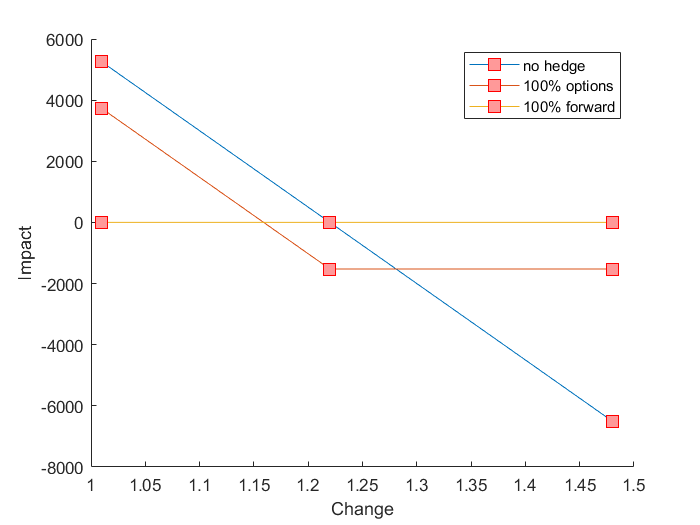

v=squeeze(impact(2, 1, :, 1));
w=squeeze(impact(2, 5, :, 1));
z=squeeze(impact(2, 5, :, 5));
figure
hold on
plot(change, v, '-s','MarkerSize',10, 'MarkerEdgeColor','red', 'MarkerFaceColor',[1 .6 .6]);
plot(change, w, '-s','MarkerSize',10, 'MarkerEdgeColor','red', 'MarkerFaceColor',[1 .6 .6]);
plot (change, z,'-s','MarkerSize',10, 'MarkerEdgeColor','red', 'MarkerFaceColor',[1 .6 .6]);
xlabel('Change');
ylabel('Impact');
legend('no hedge', '100% options', '100% forward');

Nel caso non facciamo nessuna copertura è possibile una grande perdita così come un grande guadagno. Nel caso di utilizzo di opzioni ci sarà una perdita più limitata causata dal solo costo delle opzioni, ma anche un possibile guadagno minore. Infine, nel caso di utilizzo di contratti forward non vi è un guadagno né una perdita, nella situazione di volumi certi è la soluzione più sicura, ma anche quella con nessuna possibilità di guadagno. **(COMMENTI VANNO BENE?)**

A questo punto, vogliamo provare a confrontare i diversi impatti e scegliere la soluzione che potrebbe coprirci in modo maggiore dalle variazioni. Una possibile strategia è l'analisi del worst case, quindi valutiamo il minimo per i due fattori di rischio, ovvero, come anticipato, il caso peggiore in cui potremmo trovarci dopo aver scelto una strategia (volume pari a 10000 unità e dollaro debole, infatti in questa situazione entrambi i valori sono al di sotto di quelli attesi), al variare delle percentuali di copertura e di contratti forward (rispettivamente sulle righe e sulle colonne della seguente matrice).

minMatrix = squeeze(min(min(impact,[],1),[],3));
disp(array2table(minMatrix,'VariableNames',cellstr(num2str(perc_forward')),...
                           'RowNames',cellstr(num2str(perc_cover'))));

                 0        0.25         0.5        0.75           1  
            ________    ________    ________    ________    ________

    0       -7800.00    -7800.00    -7800.00    -7800.00    -7800.00
    0.25    -6556.25    -6460.94    -6365.63    -6270.31    -6175.00
    0.5     -5312.50    -5121.88    -4931.25    -4740.63    -4550.00
    0.75    -4068.75    -3782.81    -3496.88    -3210.94    -2925.00
    1       -2825.00    -2443.75    -2062.50    -2218.75    -3150.00



Notiamo che i valori dei diversi impatti sono in generale molto bassi e quindi l'azienda è costretta ad affrontare dei costi molto elevati in questo scenario. Tuttavia, facendo riferimento ad alcuni dati reali dei tassi di cambio, ci accorgiamo che l'ipotesi che il dollaro diventi così tanto debole è abbastanza irrealistica, quindi stiamo penalizzando anche in maniera eccessiva quello che comunque risulta essere il caso peggiore. Tuttavia  per il momento assumiamo che sia possibile avere un tasso di cambio così alto e cerchiamo quale strategia riesce a farci pagare un prezzo inferiore.

Con questo obiettivo, utilizziamo la funzione *maxOfMatrix* che nel nostro caso specifico riceve in ingresso la matrice precedentemente creata e i due vettori delle percentuali di copertura e di contratti forward e restituisce la strategia a cui siamo interessati e qual è il costo massimo che saremo costretti a pagare.

maxOfMatrix(minMatrix, perc_cover, perc_forward)

max:		-2062.5
perc_cover:	1
perc_forward:	0.5


Da questo semplice ed immediato confronto, risulta che l'azienda dovrebbe scegliere di coprire tutti i costi e la metà di questi dovrebbe essere coperta con contratti forward, mentre l’altra metà con opzioni. Infatti quando siamo nello scenario peggiore, riusciamo ad ottenere il costo massimo più basso che è pari a 2062.5 USD.

## Dati reali

Poiché questa tabella con le diverse realizzazioni dei fattori di rischio è sufficientemente semplice e magari anche irrealistica, proviamo a partire dai dati reali ed usare simulazione Monte Carlo per valutare e confrontare le diverse strategie di copertura nei diversi scenari.

Per quanto riguarda i tassi di cambio, partiamo da [dati storici](https://it.investing.com/currencies/eur-usd-historical-data) (relativi agli ultimi 5 anni) e supponiamo che nel futuro questi seguiranno una distribuzione Beta, dove parametri saranno stimati proprio a partire da questi ultimi. Per farlo utilizziamo la funzione *samplingBetaFromData* che ci restituisce un campione di 200 diversi tassi di cambio campionati da una Beta e anche il relativo istogramma.

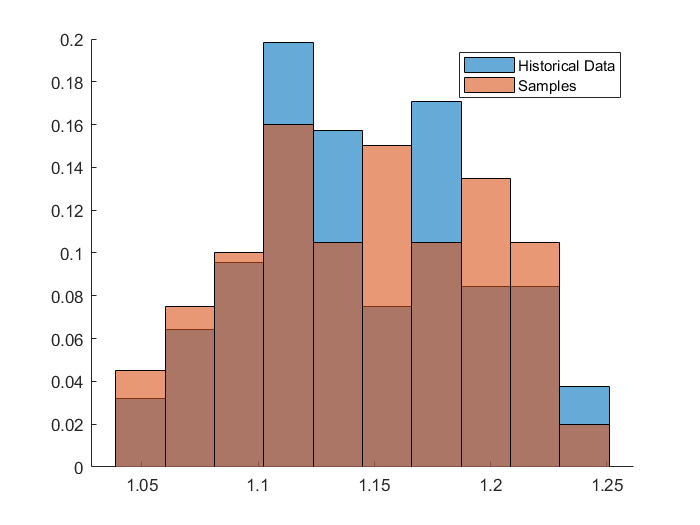

samplesChange = samplingBetaFromData(true);

Dall'istogramma notiamo che la distribuzione dei dati campionati è simile a quella dei dati storici, quindi i parametri stimati da questi ultimi sono corretti. **(VA BENE ED è UTILE?)**

Al contrario, per i diversi volumi da simulare non abbiamo a disposizione i dati storici dell’azienda, però possiamo comunque assumere che questi seguano ancora una distribuzione Beta. I parametri di questa distribuzione li abbiamo scelti arbitrariamente facendo in modo che, com’è possibile osservare dal plot della densità, abbia la più alta probabilità di essere uguale o vicina a 25000 partecipanti e poi sia un po’ spostata verso destra, quindi con una probabilità maggiore si verificheranno volumi più alti del valore atteso rispetto a valori più bassi. Una volta scelti i parametri, possiamo utilizzare la funzione *samplingBetaFromParameter* che restituice sempre 200 campioni relativi ai volumi questa volta. Inoltre nel grafico, restituito sempre dalla stessa funzione, vengono marcati i tre valori dei volumi attesi che abbiamo considerato fino a questo momento.

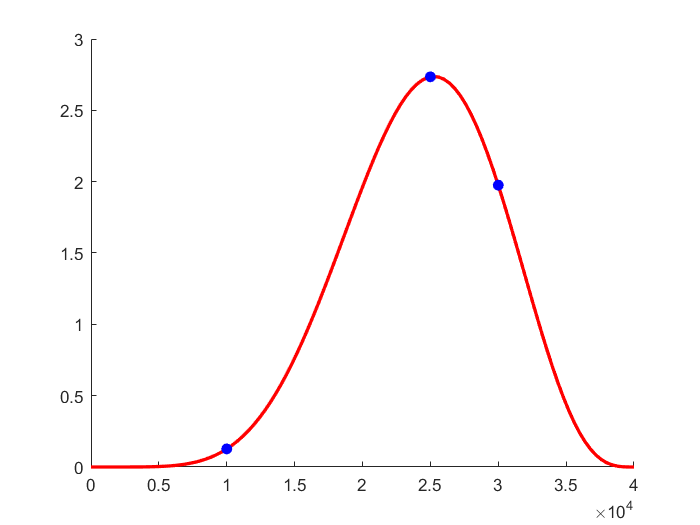

samplesVolume = samplingBetaFromParameter(7,4.5,0,40000,true,volume);

Infine, richiamiamo nuovamente la funzione *hedging_policies *per valutare i diversi impatti.

impact = hedging_policies(perc_cover, perc_forward, samplesChange, samplesVolume, volume_policy, K);

### Historical Simulation

A questo punto valutiamo le varie misure di rischio per le singole strategie e realizzazione dei fattori di rischio. Utilizziamo quindi la funzione *RiskMeasures*, passando inizialmente la stringa *‘Historical Simulation’* quindi senza fare ulteriori ipotesi. Facendo ottimizzazione robusta e quindi andando a guardare il caso peggiore dal punto di vista dell'azienda, la perdita minore la abbiamo quando decidiamo di coprire solo la metà dei nostri costi e tutti con dei contratti forward. Questa strategia ci permette di scegliere la strategia che ci fa perdere di meno nel caso peggiore ma potrebbe portare ad una scelta troppo conservativa e non permetterci di far guadagnare quando invece si realizza uno scenario favorevole per l'azienda, quindi è opportuno andare a guardare anche altre misure di rischio.

probabilities = [0.9 0.95 0.99];
[minMatrix, ~, deviazione_standard, VaR, CVaR]=RiskMeasures(probabilities, impact, 'Historical Simulation');
disp(array2table(minMatrix,'VariableNames',cellstr(num2str(perc_forward')),...
                           'RowNames',cellstr(num2str(perc_cover'))));

                     0                 0.25                  0.5                 0.75                    1       
            _________________    _________________    _________________    _________________    _________________

    0       -692.376939919546    -692.376939919546    -692.376939919546    -692.376939919546    -692.376939919546
    0.25    -952.830713748178    -857.518213748178    -762.205713748178    -666.893213748178    -571.580713748178
    0.5     -1213.28448757681    -1022.65948757681    -832.034487576809    -641.409487576809    -450.784487576809
    0.75    -1473.73826140544    -1187.80076140544    -901.863261405441    -1006.85891139078    -1532.12145043929
    1       -1734.19203523407    -1352.94203523407    -1213.

maxOfMatrix(minMatrix, perc_cover, perc_forward)

max:		-450.7845
perc_cover:	0.5
perc_forward:	1


Andando invece a considerare come misura di rischio la deviazione standard e andando poi a calcolare il minimo elemento nella matrice sfruttando nuovamente la funzione *maxOfMatrix* vediamo che la strategia più opportuna da utilizzare è quella di coprire sempre usando solo dei contratti forward, ma questa volta andando a coprire la totalità dei costi.

disp(array2table(deviazione_standard,'VariableNames',cellstr(num2str(perc_forward')),...
                                     'RowNames',cellstr(num2str(perc_cover'))));

                     0                0.25                 0.5                0.75                   1      
            ________________    ________________    ________________    ________________    ________________

    0       1304.68599382637    1304.68599382637    1304.68599382637    1304.68599382637    1304.68599382637
    0.25    1299.62826450779    1228.66941448274    1158.51665196315    1089.32572460177    1021.29213954446
    0.5     1294.74653409434    1153.68603514261    1016.54510095119    885.147451729761    762.468146738296
    0.75    1290.04280061245    1079.95108929984    880.803536926704    701.977188774751    563.174630085932
    1       1285.51901794398    1007.73865306229    754.661260473915    560.792672070943  

maxOfMatrix(-deviazione_standard, perc_cover, perc_forward)

max:		-500.4614
perc_cover:	1
perc_forward:	1


Se invece vogliamo considerare una misura di rischio che tenga conto delle asimmetrie, consideriamo il V@R oppure il CV@R. Con la prima misura di rischio, andando a considerare una probabilità del 99%, otteniamo che la strategia ottimale da scegliere è la stessa che ci suggeriva l'ottimizzazione worst-case anche se ovviamente il valore di massimo raggiunto è diverso perchè stiamo considerando un altro indice. Per avere un'idea più immediata di quello che realmente accade è possibile considerare una heat-map. Nella prima riga ovviamente il risultato sarà sempre lo stesso perchè stiamo scegliendo di non coprire, quindi non avrebbe nemmeno senso considerare le diverse percentuali di contratto forward perchè il volume coperto sarà sempre nullo. Notiamo inoltre che i valori più bassi si ottengono nell'ultima riga, quindi questo vuol dire quando scegliamo di coprire tutti i costi. Infatti questo potrebbe essere dovuto al fatto che nella maggior parte delle realizzazioni dei due fattori di rischio abbiamo comprato più valuta di quanta davvero era necessaria.

disp(array2table(squeeze(VaR(3,:,:)),'VariableNames',cellstr(num2str(perc_forward')),...
                                     'RowNames',cellstr(num2str(perc_cover'))));

                     0                 0.25                  0.5                 0.75                    1       
            _________________    _________________    _________________    _________________    _________________

    0        -381.92012688665     -381.92012688665     -381.92012688665     -381.92012688665     -381.92012688665
    0.25    -664.621612010305    -569.309112010305    -473.996612010305    -378.684112010305    -283.371612010305
    0.5     -953.547285843141    -762.922285843141    -572.297285843141    -381.672285843141    -243.698801607743
    0.75    -1249.40539186758    -963.467891867578    -677.530391867578      -536.4258574476     -752.81489691224
    1       -1553.76767711541    -1172.51767711541    -890.7

maxOfMatrix(squeeze(VaR(3,:,:)), perc_cover, perc_forward)

max:		-243.6988
perc_cover:	0.5
perc_forward:	1


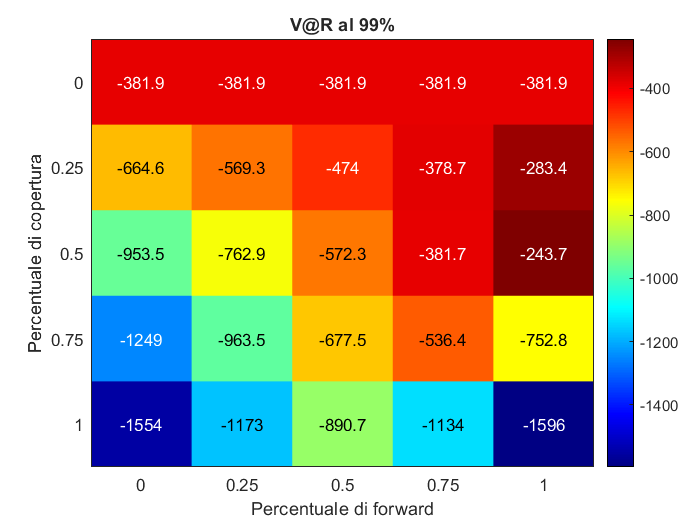

heatmap(perc_cover, perc_forward,squeeze(VaR(3,:,:)),'Title','V@R al 99%', ...
        'XLabel','Percentuale di forward','YLabel','Percentuale di copertura', ...
        'GridVisible','off','Colormap',jet);

Infine come ultimo tentativo, consideriamo il CV@R come misura di rischio che è coerente, convessa e valuta il valore atteso della perdita, condizionatamente al fatto che la perdita è andata oltre il muro che avevamo fissato con il V@R. Di nuovo andiamo a considerare il livello di probabilità al 99%, quello che osserviamo è che i risultati sembrano essere coerenti con quanto suggerito dal V@R. **(ALTRO??)**

disp(array2table(squeeze(CVaR(3,:,:)),'VariableNames',cellstr(num2str(perc_forward')),...
                                      'RowNames',cellstr(num2str(perc_cover'))));

                     0                 0.25                  0.5                 0.75                    1       
            _________________    _________________    _________________    _________________    _________________

    0       -490.326513824217    -490.326513824217    -490.326513824217    -490.326513824217    -490.326513824217
    0.25    -758.908936957509    -663.596436957508    -568.283936957508    -472.971436957508    -377.658936957508
    0.5     -1030.48539588527    -839.860395885267    -649.235395885267    -458.610395885267    -310.172294148916
    0.75    -1308.68973054968    -1022.75223054968    -736.814730549677    -692.011577986546    -992.245264488526
    1       -1597.42564858044    -1216.17564858044    -998.6

maxOfMatrix(squeeze(CVaR(3,:,:)), perc_cover, perc_forward)    

max:		-310.1723
perc_cover:	0.5
perc_forward:	1


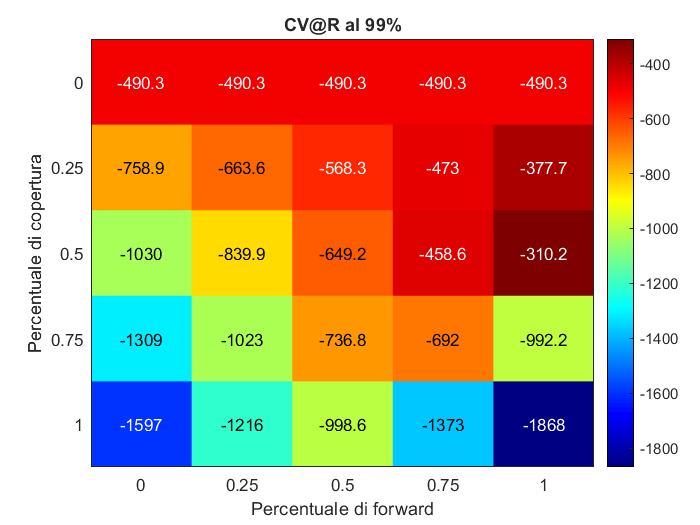

heatmap(perc_cover, perc_forward,squeeze(CVaR(3,:,:)),'Title','CV@R al 99%', ...
        'XLabel','Percentuale di forward','YLabel','Percentuale di copertura', ...
        'GridVisible','off','Colormap',jet);

### Parametric Beta **(SERVE? Da controllare)**

%[minMatrix, varianza, deviazione_standard, VaR, CVar]=RiskMeasures(probabilities, impact,...
%    'Parametric Beta');
%squeeze(VaR(3,:,:))
%maxOfMatrix(squeeze(VaR(3,:,:)), perc_cover, perc_forward)
%heatmap(perc_cover, perc_forward,squeeze(VaR(3,:,:)),'Title','V@R al 99%', ...
%    'XLabel','Percentuale di forward','YLabel','Percentuale di copertura', ...
 %   'GridVisible','off','Colormap',jet);

### Parametric Normal

Un alternativa al precedente modo in cui abbiamo calcolato le misure di rischio è utilizzare sempre la stessa funzione *RiskMeasures* questa volta passando però la stringa '*Parametric Normal'*. Facendo un assunzione abbastanza forte e ovvero che i valori campionati seguano una distribuzione normale.

[~, ~, ~, VaR, CVaR]=RiskMeasures(probabilities, impact, 'Parametric Normal');

Tuttavia le code di una distribuzione normale hanno valori irrealistici che pesano troppo nel calcolo dei valori, ad esempio confrontiamo il valore del V@R  e del CV@R della normale parametrica con quello calcolato precedentemente dai dati storici.

disp(array2table(squeeze(VaR(3,:,:)),'VariableNames',cellstr(num2str(perc_forward')),...
                                     'RowNames',cellstr(num2str(perc_cover'))));

                     0                 0.25                  0.5                 0.75                    1       
            _________________    _________________    _________________    _________________    _________________

    0       -1244.85443603694    -1244.85443603694    -1244.85443603694    -1244.85443603694    -1244.85443603694
    0.25    -1611.15402551162    -1468.18652533598    -1327.09426511494    -1188.23956806936    -1052.07725183242
    0.5     -1977.86304966506     -1693.9221972666    -1419.09961601541    -1157.63791354419    -916.458112637486
    0.75    -2344.98615660185    -1922.56215980966    -1525.59808389951    -1175.90819822724    -919.327570083586
    1       -2712.52789173086    -2154.74400933607    -1654.

maxOfMatrix(squeeze(VaR(3,:,:)), perc_cover, perc_forward)  

max:		-916.4581
perc_cover:	0.5
perc_forward:	1


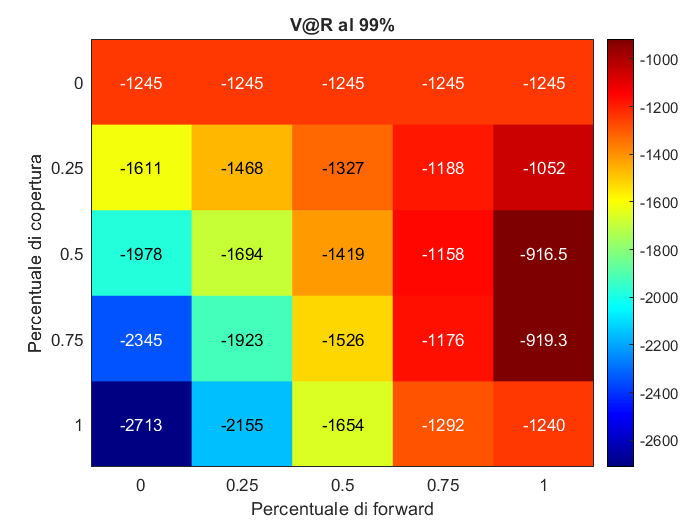

heatmap(perc_cover, perc_forward,squeeze(VaR(3,:,:)),'Title','V@R al 99%', ...
        'XLabel','Percentuale di forward','YLabel','Percentuale di copertura', ...
        'GridVisible','off','Colormap',jet);

disp(array2table(squeeze(CVaR(3,:,:)),'VariableNames',cellstr(num2str(perc_forward')),...
                                      'RowNames',cellstr(num2str(perc_cover'))));

                     0                0.25                 0.5                0.75                   1      
            ________________    ________________    ________________    ________________    ________________

    0       3094.98504581826    3094.98504581826    3094.98504581826    3094.98504581826    3094.98504581826
    0.25    2711.86168917726     2618.7953694277     2526.5351371836    2435.23674009774    2345.09568531591
    0.5     2328.91433144138    2143.63889304064    1962.28301940021    1786.67043072977     1619.7761862893
    0.75    1946.14497063707    1669.73085015094    1404.26088860429    1159.11213127883    953.987163416491
    1       1563.55556064618    1197.34531686647     855.83804538007    573.539578079079  

maxOfMatrix(squeeze(CVaR(3,:,:)), perc_cover, perc_forward)  

max:		3094.985
perc_cover:	0
perc_forward:	0


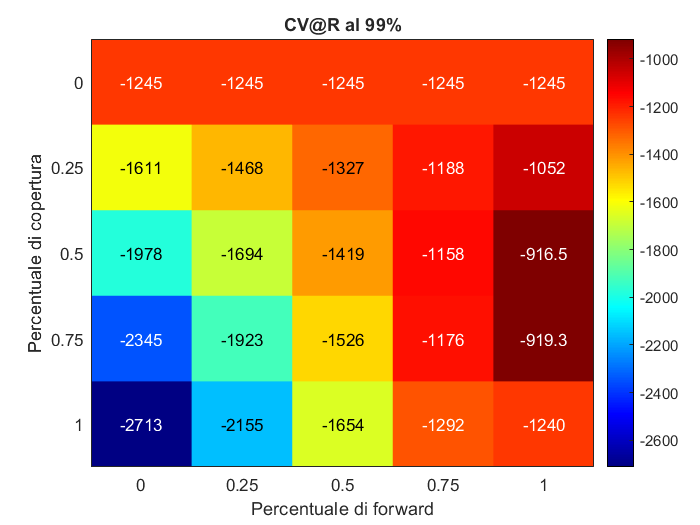

heatmap(perc_cover, perc_forward, squeeze(CVaR(3,:,:)),'Title','CV@R al 99%', ...
        'XLabel','Percentuale di forward','YLabel','Percentuale di copertura', ...
        'GridVisible','off','Colormap',jet);

## Dati reali ma con più "politiche"

Come già anticipato inizialmente, l’assunzione di utilizzare solamente 5 valori di percentuali sia per la copertura che per i contratti forward è abbastanza irrealistico. Per migliorare questo aspetto, andiamo a discretizzare l’intervallo [0,1] a passi di 0.01 e ripetiamo quanto fatto finora andando a ragionare sul V@R. Ancora una volta osservando la heat-map, notiamo che i valori più bassi del V@R si trovano nella parte inferiore della matrice, quindi quando aumenta la percentuale di copertura. 

perc_cover = [0:0.01:1];
perc_forward = [0:0.01:1];
impact = hedging_policies(perc_cover, perc_forward, samplesChange, samplesVolume,...
                          volume_policy, K);
[minMatrix, varianza, deviazione_standard, VaR, CVar]=RiskMeasures(probabilities, ...
    impact, 'Historical Simulation');
disp(array2table(squeeze(VaR(3,:,:)),'VariableNames',cellstr(num2str(perc_forward')),...
                                     'RowNames',cellstr(num2str(perc_cover'))));

                     0                 0.01                 0.02                 0.03                 0.04                 0.05                 0.06                 0.07                 0.08                 0.09                  0.1                 0.11                 0.12                 0.13                 0.14                 0.15                 0.16                 0.17                 0.18                 0.19                  0.2                 0.21                 0.22                 0.23                 0.24                 0.25           

maxOfMatrix(squeeze(VaR(3,:,:)), perc_cover, perc_forward)

max:		-211.2287
perc_cover:	0.45
perc_forward:	1


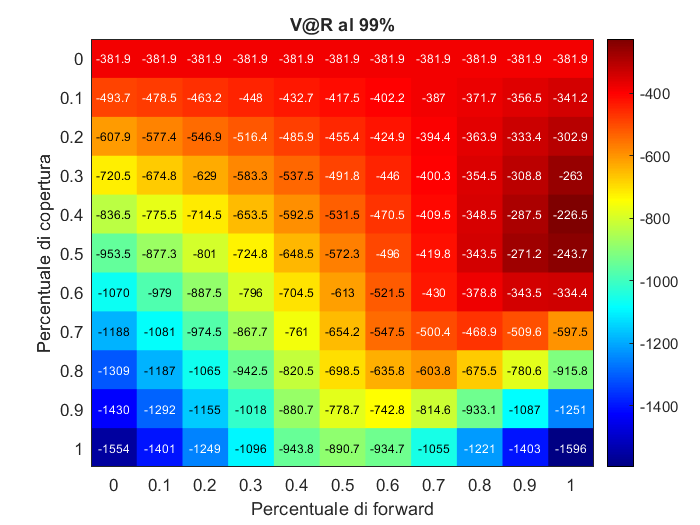

heatmap(perc_cover(1:10:101),perc_forward(1:10:101),squeeze(VaR(3,1:10:101,1:10:101)), ...
        'Title','V@R al 99%', 'XLabel','Percentuale di forward','YLabel','Percentuale di copertura', ...
        'GridVisible','off','Colormap',jet);

## Conclusione

**(AGGIUNGERE CONCLUSIONE)**

## APPENDICE

#### Funzione `hedging_policies`

Nella funzione `hedging_policies` creiamo la matrice degli impatti in base alla diversa strategia scelta e a seconda delle realizzazioni dei due fattori di rischio. La matrice che consideriamo ha le seguenti dimensioni: i diversi volumi di vendita possibili, le diverse percentuali di copertura, le diverse percentuali di contratti forward e i diversi valori di cambio. Grazie all’utilizzo di diversi cicli for annidati, riusciamo a coprire tutte le diverse casistiche andando nello specifico a distinguere il caso più immediato in cui non viene fatta copertura, da quello in cui scegliamo di coprire una certa percentuale dei costi e a quel punto, facendo variare la percentuale di copertura con un contratto forward. Nel caso in cui vengano utilizzate anche delle opzioni per fare copertura è necessario andare ad includere anche il prezzo che l’azienda deve pagare per entrare nel contratto (il 5% del valore). Infine quindi l’impatto totale della strategia scelta sarà uguale alla somma tra il costo dell’opzione (quando viene utilizzata, zero altrimenti), l’impatto dato dal volume che rimane scoperto (e che quindi l’azienda pagherà al tasso di cambio effettivo invece che a quello atteso) e infine dall’impatto dovuto al volume che abbiamo deciso di coprire.

function [impact] = hedging_policies(perc_cover, perc_forward, change, volume, volume_policy, K)

impact = zeros(length(volume),length(perc_cover),length(change),length(perc_forward));

for i = 1:length(volume)
    for j = 1:length(perc_cover)
        volume_no_cover = volume(i) - volume_policy*perc_cover(j);
        for k = 1:length(change)
            if perc_cover(j) == 0
                impact_no_cover = volume(i)*(K-change(k));
                impact(i,j,k,:) = ones(length(perc_forward),1)*impact_no_cover;
            else
                for w = 1:length(perc_forward)
                    volume_options = volume_policy*perc_cover(j)*(1-perc_forward(w));

                    cost_options = -volume_options*K*0.05;

                    impact_no_cover = volume_no_cover*(K-change(k));

                    impact_cover = volume_options*max(K-change(k),0);

                    impact(i,j,k,w) = cost_options + impact_no_cover + impact_cover;
                end
            end
        end
    end
end
end

#### Funzione *maxOfMatrix*

La funzione *maxOfMatrix* riceve in ingresso una matrice della quale vogliamo trovare l'elemento massimale e a quale situazione corrisponde quello specifico valore. La funzione riceve in ingresso anche due vettori che sono quelli associati ai diversi valori di riga e colonna presenti nella matrice. Gli output della funzione sono per l'appunto il valore massimo della matrice e, dopo aver  trovato la sua pozione all'interno della matrice, i corrispondenti valori dei vettori che danno i nomi rispettivamente alle colonne e alle righe della matrice.

function [] = maxOfMatrix(matrix, perc_cover, perc_forward)
[M,id] = max(matrix,[],'all','linear');
numR = length(perc_cover);
idC = ceil(id/numR);
idR = id-numR*(idC-1);
fprintf("max:\t\t" + M + "\n")
fprintf("perc_cover:\t" + perc_cover(idR) + "\n");
fprintf("perc_forward:\t" + perc_forward(idC) + "\n");
end

#### Funzione *samplingBetaFromData*

La funzione *samplingBetaFromData* restituisce un campione di elementi estratti da una distribuzione Beta, i cui parametri vengono stimati a partire da dati reali. Nello specifico abbiamo usato il file *"EUR_USD Dati Storici.csv" *che raccoglie i dati giornalieri del tasso di cambio euro-dollaro degli ultimi 5 anni presi dal sito [Investing](https://it.investing.com/currencies/eur-usd-historical-data).

Poiché la distribuzione Beta è definita sull'intervallo unitario [0,1], per prima cosa normalizziamo i dati dopo averli importati dal file e successivamente calcoliamo la media e la varianza campionaria andando ad utilizzare le funzione già implementate in Matlab. A questo punto, utilizziamo le formule proprie della Beta andando a calcolare i due parametri caratteristici *alpha* e *beta* andando a sostituire nelle rispettive formule i valori campionari.


$$\alpha=\left(\frac{1-\hat{\mu}}{\hat{\sigma}^2}-\frac{1}{\hat{\mu}}\right)\hat{\mu}^2$$
          
$$\beta=\alpha\left(\frac{1}{\hat{\mu}}-1\right)$$


Infine utilizziamo la funzione *betarnd* per campionare 200 elementi dalla distribuzione Beta con i parametri appena calcolati e denormalizziamo nuovamente i valori per trovare dei tassi di cambio sensati. Inoltre se l’utente vuole avere un’idea più immediata di quello che accade, è possibile passare una variabile binaria che, quando settata a *true*, restituisce un istogramma sia dei dati storici che di quelli campionati in modo da confrontarli.

function samples = samplingBetaFromData(plotHist,fileName,seed)
format long
if nargin == 0
    plotHist = false;
    fileName = 'EUR_USD Dati Storici.csv';
    seed = 'default';
elseif nargin == 1
    fileName = 'EUR_USD Dati Storici.csv';
    seed = 'default';
elseif nargin == 2
    seed = 'default';
elseif nargin>3
    error('Too many input arguments.');
end
historical_data_table = readtable(fileName,'PreserveVariableNames',true).Ultimo;
historical_data = str2double(strrep(string(historical_data_table),',','.'));

minValue = min(historical_data);
maxValue = max(historical_data);
hd_norm = (historical_data-minValue) / (maxValue-minValue);
muHD = mean(hd_norm);
varHD = var(hd_norm);

alpha = ((1 - muHD) / varHD - 1 / muHD) * muHD ^ 2;
beta = alpha * (1 / muHD - 1);

rng(seed) % For reproducibility
samples = betarnd(alpha,beta,[200,1])*(maxValue-minValue)+minValue;
if plotHist
    minPlot = min([minValue,samples']);
    maxPlot = max([maxValue,samples']);
    figure
    hold on
    histogram(historical_data,10,'Normalization','probability','BinLimits',[minPlot,maxPlot])
    histogram(samples,10,'Normalization','probability','BinLimits',[minPlot,maxPlot])
    legend('Historical Data','Samples')
    hold off
end
end

#### Funzione *SamplingBetaFromParameter*

Simile alla funzione precedente, questa volta vogliamo campionare dei valori da una distribuzione Beta non basandoci su dati reali, ma passando direttamente i parametri *alpha* e *beta* della distribuzione. La funzione *SamplingBetaFromParameter* riceve infatti in input i due parametri *alpha* e *beta*, il valore minimo e quello massimo dell'intervallo in cui otteniamo dei valori ragionevoli a seconda dei dati da voler campionare (abbiamo quindi bisogno di riscalare i valori in quanto la distribuzione Beta è definita solo sull’intervallo unitario). Inoltre, può ricevere in input dei parametri opzionali che sono rispettivamente una variabile booleana per plottare il grafico della funzione che otteniamo, un vettore di punti importanti che eventualmente sanno marcati sul grafico, e un seme casuale utile per riprodurre la simulazione (se questo non viene passato, verrà assegnato il parametro di default). L’output della funzione sarà quindi il campione di 200 elementi campionati dalla distribuzione Beta di interesse e riscalati in base all’ampiezza dell’intervallo.

function samples = samplingBetaFromParameter(alpha,beta,minValue,maxValue,...
                        plotDensity,importantValues,seed)
format long
if nargin<4
    error('Not enough input arguments.');
elseif nargin == 4
    plotDensity=false;
    importantValues=[];
    seed = 'default';
elseif nargin == 5
    importantValues=[];
    seed = 'default';
elseif nargin == 6
    seed = 'default';
elseif nargin>7
    error('Too many input arguments.');
end

rng(seed) % For reproducibility
samples = betarnd(alpha,beta,[200,1])*(maxValue-minValue)+minValue;

if plotDensity
    X = 0:.01:1;
    y = betapdf(X,alpha,beta);
    importantValues_pdf = betapdf((importantValues-minValue)/(maxValue-minValue),alpha,beta);
    figure
    hold on
    plot(X*(maxValue-minValue)+minValue,y,'LineStyle','-','Color','r','LineWidth',2);
    plot(importantValues,importantValues_pdf,'o','MarkerFaceColor','blue',...
        'MarkerEdgeColor','blue');
    hold off
end
end

#### Funzione *RiskMeasures*

La funzione riceve in input un vettore o uno scalare che indica il livello di probabilità per cui vanno calcolate alcune specifiche misure di rischio, la matrice impact con i diversi costi da sostenere per l’azienda nei diversi scenari e una stringa che indica in che modo andare a calcolare le varie misure di rischio. 

Le misure di rischio che andiamo a considerare sono diverse e ciascuna sarà caratterizzata da vantaggi e svantaggi:

- VARIANZA e DEVIAZIONE STANDARD $\Rightarrow$ sono due misure di rischio che quantificano la dispersione, ma non tengono conto della direzione in quanto sono due misure simmetriche. Inoltre si dimostra che non sono delle misure di rischio coerenti in quanto ad esempio la varianza non è invariante per traslazioni né monotona, ma nemmeno positiva omogenea o sub-additiva (mentre la deviazione standard lo è). Quindi nonostante la limitazione principale che riguarda la simmetria, sicuramente tra le due misure andremo a considerare la deviazione standard.

- VALUE-AT-RISK e CONDITIONAL VALUE-AT-RISK $\Rightarrow$ sono due misure collegate in qualche modo al quantile della CDF della variabile. Per il V@R tutte le proprietà di una misura di rischio coerente sono verificate, tranne in generale la sub-additività. Nel caso particolare di una normale però, vale anche quest’ultima proprietà. Tuttavia il value-at-risk potrebbe aprire la strada a strategie molto rischiose per un investitore perché non riesce a dare informazioni relative alla forma della coda e anche se abbiamo delle perdite maggiori del V@R solo in poche occasioni, non sappiamo quale sia l’entità di queste perdite. Per questo motivo è stato introdotto il CV@R che calcola il valore atteso della perdita quando si va oltre la soglia. Questa misura è asimmetrica  e inoltre si può dimostrare che questa misura è coerente e convessa, anche se in generale non può essere calcolato direttamente, ma va valutato numericamente.

Se la variabile type contiene la stringa *'Historical Simulation'* allora la funzione calcola la media e la varianza campionaria per usare quest’ultima e la sua radice quadrata come misure di rischio e poi ordina i possibili scenari (quindi per ogni strategia di hedging per ogni possibile realizzazione del tasso di cambio e dei volumi di vendita) i modo da considerare solamente 

Se la variabile type contiene la stringa *'Parametric Normal’*, allora ancora la varianza e la deviazione standard vengono calcolate nello stesso modo, ma questa volta stiamo supponendo che le variabili seguano una distribuzione normale quindi possiamo semplicemente invertire la distribuzione di probabilità per calcolare il quantile che quindi coincide con il V@R e poi il questo caso specifico abbiamo una formula chiusa anche per il calcolo del CV@R. 

**(PARAMETRIC BETA NON SO SE SIA GIUSTO, si può togliere??)**

function [minMatrix,sigma_squared, sigma, VaR, CVaR] = RiskMeasures(probabilities, impact, type)
%RISKMEASURE Summary of this function goes here
%   Detailed explanation goes here

s=size(impact);
num_perc_cover=s(2);
num_perc_forward=s(4);
num_prob=length(probabilities);

sigma_squared = zeros(num_perc_cover, num_perc_forward);
sigma = zeros(num_perc_cover, num_perc_forward);
VaR = zeros(num_prob,num_perc_cover, num_perc_forward);
%scen = zeros(num_perc_cover, num_perc_forward);
%err_VaR = zeros(num_perc_cover, num_perc_forward);
CVaR = zeros(num_prob,num_perc_cover, num_perc_forward);

%%OTTIMIZZAZIONE ROBUSTA
% trovo il minimo lungo la dimensione del volume (dim 1) e lungo quella del
% change (dim 3) e poi sistemo la matrice per eliminare le dimensioni di 
% lunghezza 1
minMatrix = squeeze(min(min(impact,[],1),[],3));
for i = 1:num_perc_cover
    for j = 1:num_perc_forward %per ogni strategia
        scenari=squeeze(impact(:, i, :, j));
        
        
        %===========================
        %     Parametric Beta
        %===========================
        if strcmp(type,'Parametric Beta')
            minValue = min(scenari,[],'All');
            maxValue = max(scenari,[],'All');
            scenari_norm = (scenari-minValue) / (maxValue-minValue);
            muC=1/numel(scenari_norm)*sum(scenari_norm,'All');
            varC=1/(numel(scenari_norm)-1)*sum((scenari_norm).^2-muC^2,'All');
            alpha = ((1 - muC) / varC - 1 / muC) * muC ^ 2;
            beta = alpha * (1 / muC - 1)-1+muC;
            %sigma_squared(i, j)= alpha*beta/((alpha+beta+1)*(alpha+beta)^2);
            sigma_squared(i,j)=1/(numel(scenari)-1)*sum((scenari).^2-muC^2,'All');
            sigma(i,j)=sqrt(sigma_squared(i,j));
            for prob=1:length(probabilities)
                VaR(prob,i,j)=betainv(1-probabilities(prob), alpha,beta)*(maxValue-minValue)+minValue;
                CVaR(prob,i,j)= 1/(1-probabilities(prob))*betacdf(VaR(prob,i,j),alpha,beta); %non l'ho capito
            end
        end
        
        %===========================
        %     Parametric Normal
        %===========================
        if strcmp(type,'Parametric Normal')
            muC=1/numel(scenari)*sum(scenari,'All');
            varC=1/(numel(scenari)-1)*sum((scenari).^2-muC^2,'All');
            sigma_squared(i,j)= varC;
            sigma(i,j)=sqrt(sigma_squared(i,j));
            for prob=1:length(probabilities)
                VaR(prob,i,j)=norminv(1-probabilities(prob),muC,sigma(i,j));
                CVaR(prob,i,j)= muC+sigma(i,j)/(1-probabilities(prob))*normcdf(VaR(prob,i,j),muC,sigma(i,j)); 
            end
        end
        
        
        %============================
        %    Historical Simulation
        %============================
        if strcmp(type,'Historical Simulation')
            muC=1/numel(scenari)*sum(scenari,'All');
            varC=1/(numel(scenari)-1)*sum((scenari).^2-muC^2,'All');
            sigma_squared(i,j)= varC;
            sigma(i,j)=sqrt(sigma_squared(i,j));
            for prob=1:length(probabilities)
                id=floor(numel(scenari)*(1-probabilities(prob)));
                scenari_sort = sort(reshape(scenari,1,[]));
                VaR(prob,i,j) = scenari_sort(id);
                CVaR(prob,i,j) = mean(scenari_sort(1:id));
            end
            %VaR(i,j) = prctile(scenari,100-probability*100,'all');
            %err_VaR(i,j) = min(abs(squeeze(impact(:,i,:,j))-VaR(i,j)),[],'All');
            
        end
    end
end
end